**Excersise 1**

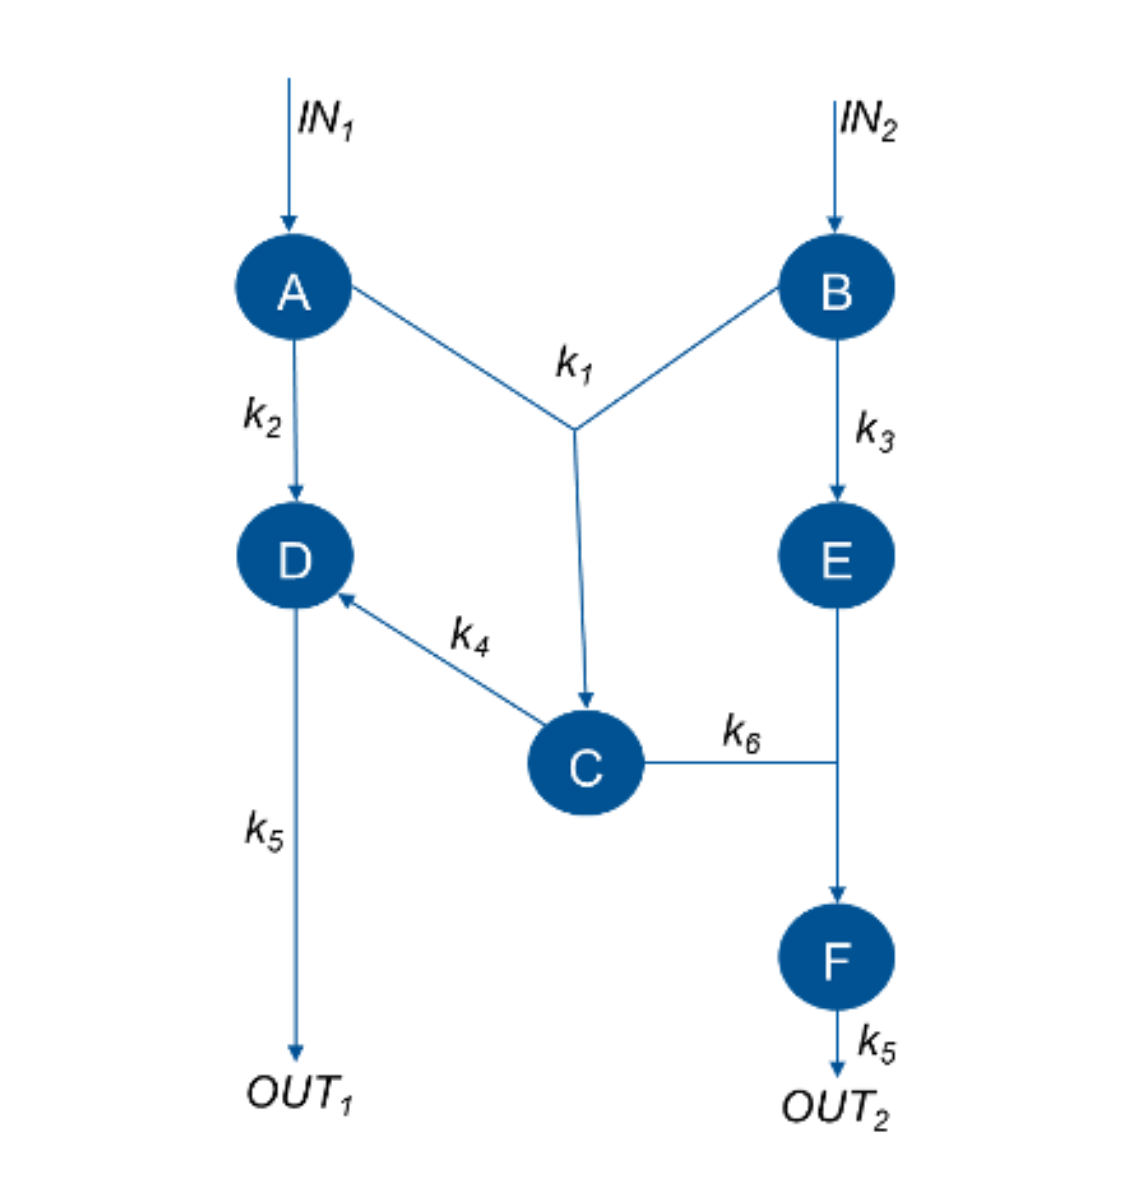

1. In this exercise, you again will simulate the dynamics of the system depicted in figure 1but this time with the RK4 method. The kinetic parameters of the network remain the same and are available on Moodle saved into the ’pEuler2.mat’

a. Integrate the kinetic parameters (k1 to k6) into your MATLAB script.

b. Implement a function file with the differential equations for the components (you should already have these from last weeks exercise), that you can use an input for the ode45 function.

k = [0.7500, 1.0000, 0.6000, 0.2000, 1.5000, 1.2500];
y0 = zeros(1, 8);
y0(1) = 0.5;
IN = [1, 0.5];
time = 0:0.01:10;

c. Simulate the systems dynamics in the time range [0,10] for constant input values IN1 = 1 and IN2 = 0.5. All chemical components should be initialized at 0, except for A, which should have an initial value of 0.5 . Use global variables to pass the values for IN1 and IN2 to your function file.

[time, concentration] = ode45(@(t,initCond) odeSystem(t, initCond, k, IN) ,time, y0);

d. Plot the results of the simulation in two separate figures, one for the chemical components and one for the output values.

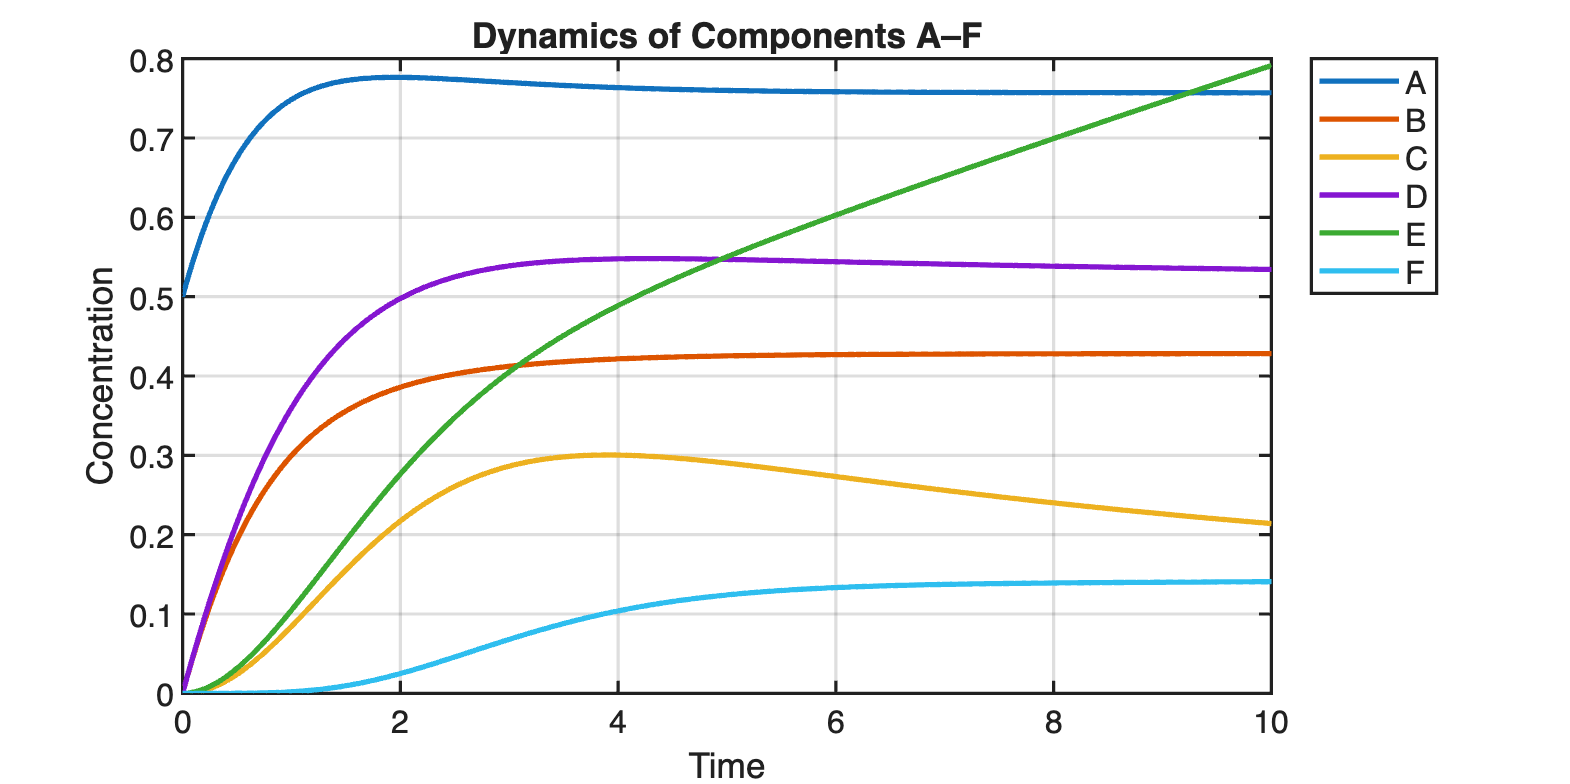

figure(1)
set(gcf, 'Position', [200 200 1200 600]);   

plot(time, concentration(:,1), 'LineWidth', 2); hold on;
plot(time, concentration(:,2), 'LineWidth', 2);
plot(time, concentration(:,3), 'LineWidth', 2);
plot(time, concentration(:,4), 'LineWidth', 2);
plot(time, concentration(:,5), 'LineWidth', 2);
plot(time, concentration(:,6), 'LineWidth', 2);

grid on;
xlabel('Time', 'FontSize', 14);
ylabel('Concentration', 'FontSize', 14);
title('Dynamics of Components A–F', 'FontSize', 16);

legend({'A','B','C','D','E','F'}, ...
       'Location', 'bestoutside', ...
       'FontSize', 12);

set(gca, 'FontSize', 12, 'LineWidth', 1.2); 
hold off;

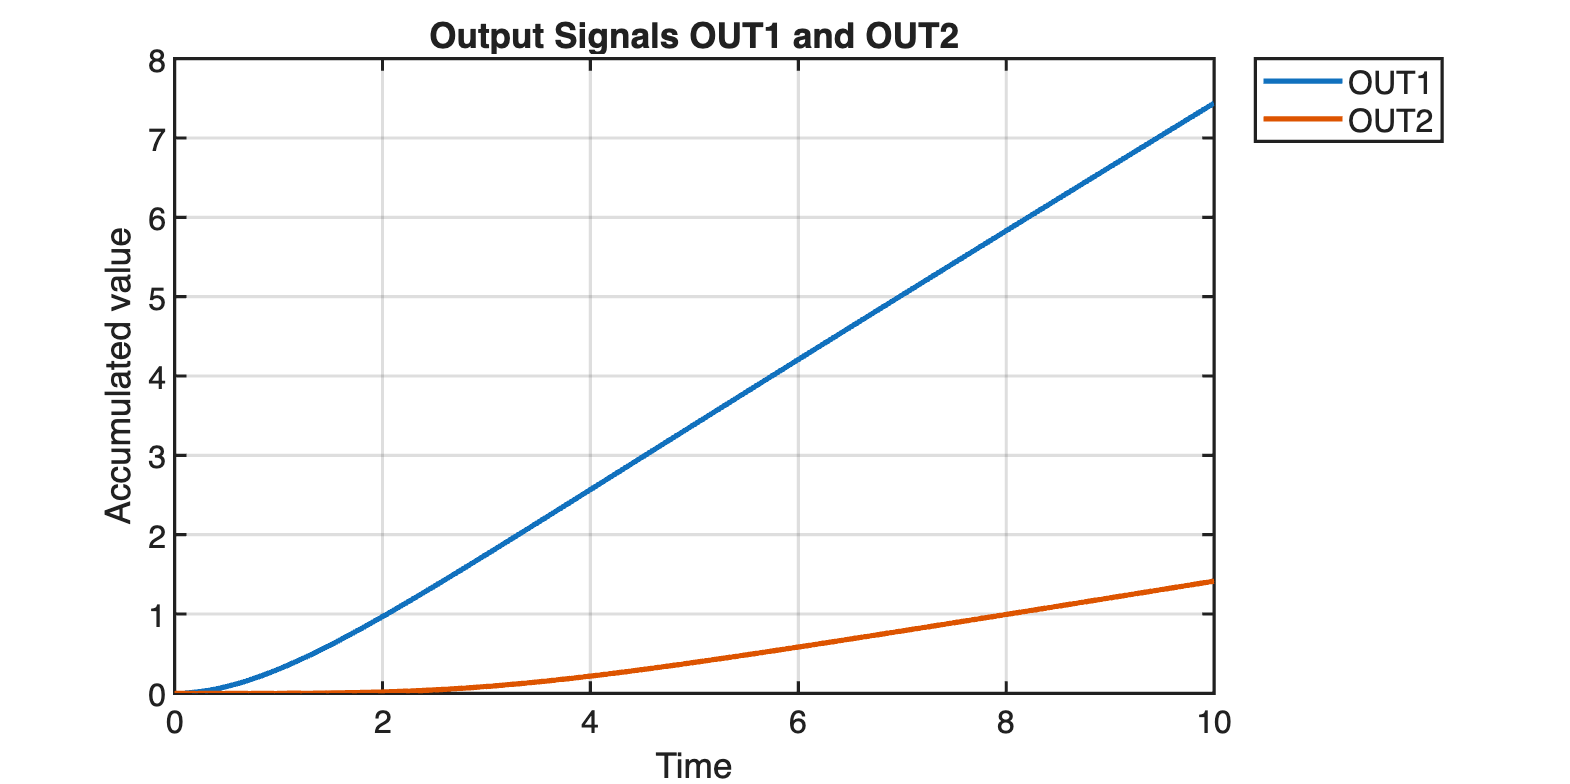


figure(2)
set(gcf, 'Position', [200 200 1200 600]);   

plot(time, concentration(:,7), 'LineWidth', 2); hold on;
plot(time, concentration(:,8), 'LineWidth', 2);

grid on;
xlabel('Time', 'FontSize', 14);
ylabel('Accumulated value', 'FontSize', 14);
title('Output Signals OUT1 and OUT2', 'FontSize', 16);

legend({'OUT1','OUT2'}, ...
       'Location', 'bestoutside', ...
       'FontSize', 12);

set(gca, 'FontSize', 12, 'LineWidth', 1.2); 
hold off;

e. Now, perform the same simulation, but with limited inputs. In this case, IN1 = 1 only in the time frame [0,2], whereas IN2 = 0.5 only in the time frame [0.5 , 2.5]. In the remaining time frames, IN1 and IN2 equal 0. All other characteristics remain the same. In order to do this, you could adept your existing function file by removing IN1 and IN2 as global variable and instead define them in the function with some additional conditions that make them adopt the correct values in the right time frame. Make a plot of your results, including the simulations of all variables + outputs as well as the varying of your input.

[time, concentration] = ode45(@(t,initCond) odeSystem(t, initCond, k, input(t)) ,time, y0);

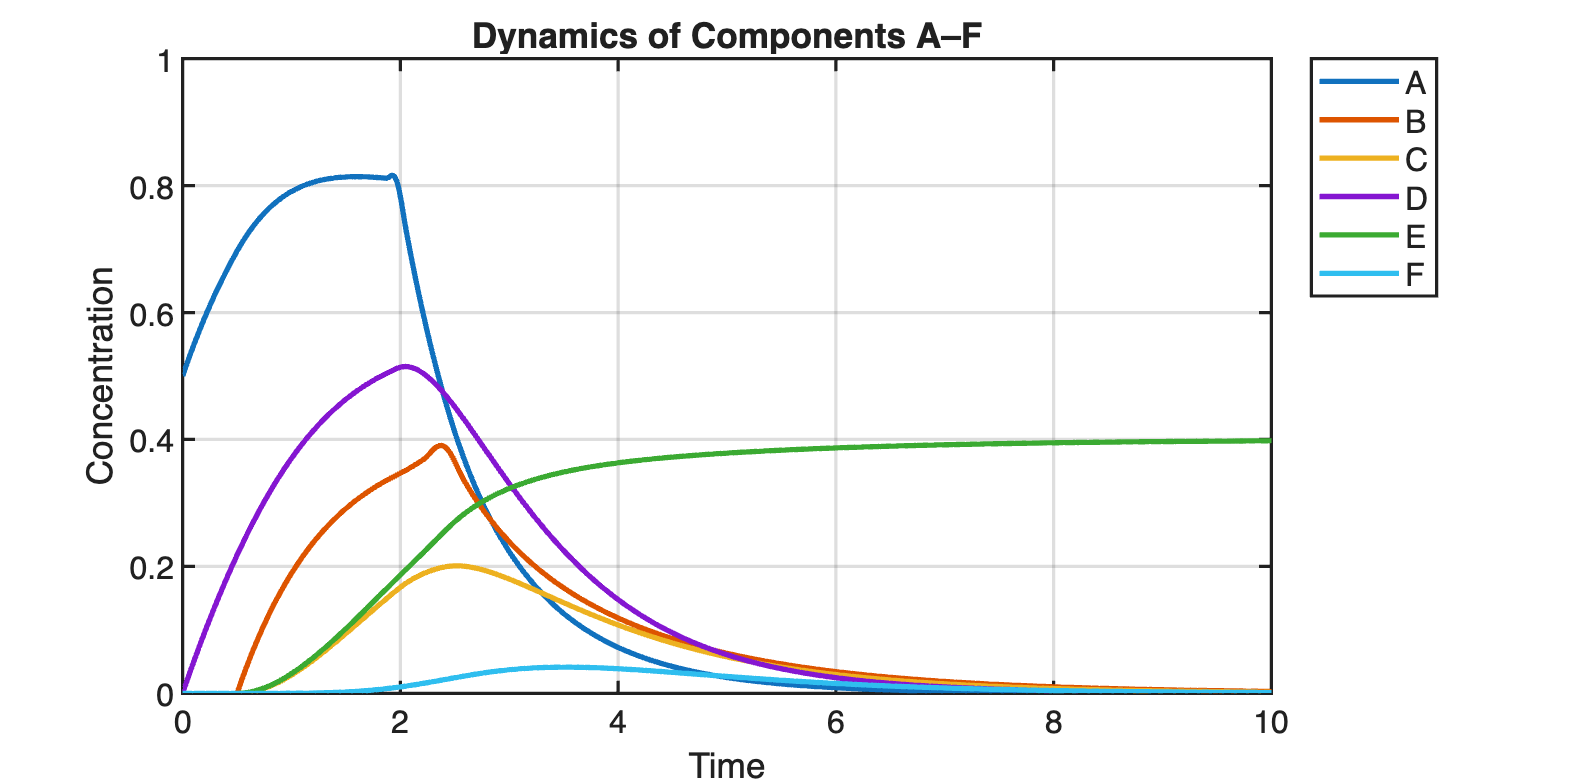

figure(3)
set(gcf, 'Position', [200 200 1200 600]);   

plot(time, concentration(:,1), 'LineWidth', 2); hold on;
plot(time, concentration(:,2), 'LineWidth', 2);
plot(time, concentration(:,3), 'LineWidth', 2);
plot(time, concentration(:,4), 'LineWidth', 2);
plot(time, concentration(:,5), 'LineWidth', 2);
plot(time, concentration(:,6), 'LineWidth', 2);

grid on;
xlabel('Time', 'FontSize', 14);
ylabel('Concentration', 'FontSize', 14);
title('Dynamics of Components A–F', 'FontSize', 16);

legend({'A','B','C','D','E','F'}, ...
       'Location', 'bestoutside', ...
       'FontSize', 12);

set(gca, 'FontSize', 12, 'LineWidth', 1.2); 
hold off;

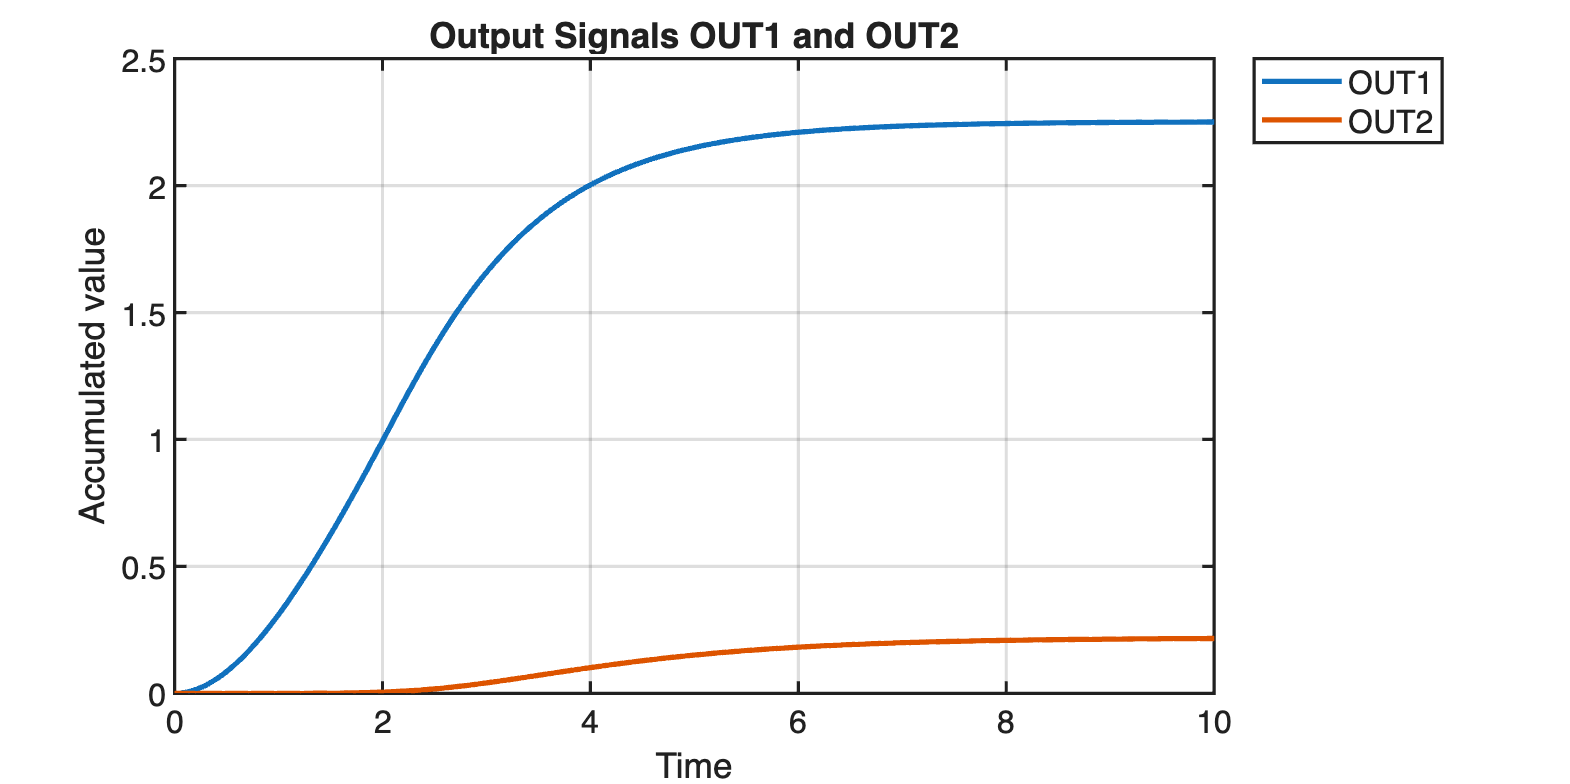


figure(4)
set(gcf, 'Position', [200 200 1200 600]);   

plot(time, concentration(:,7), 'LineWidth', 2); hold on;
plot(time, concentration(:,8), 'LineWidth', 2);

grid on;
xlabel('Time', 'FontSize', 14);
ylabel('Accumulated value', 'FontSize', 14);
title('Output Signals OUT1 and OUT2', 'FontSize', 16);

legend({'OUT1','OUT2'}, ...
       'Location', 'bestoutside', ...
       'FontSize', 12);

set(gca, 'FontSize', 12, 'LineWidth', 1.2); 
hold off;

%% Local functions
function concentrations = odeSystem(t, initialState, k, IN)

    A = initialState(1);
    B = initialState(2);
    C = initialState(3);
    D = initialState(4);
    E = initialState(5);
    F = initialState(6);

    concentrations = zeros(8, 1);

    concentrations(1) = IN(1) - k(1) * A * B - k(2) * A;
    concentrations(2) = IN(2) - k(1) * A * B - k(3) * B;
    concentrations(3) = k(1) * A * B - k(4) * C - k(6) * C * E;
    concentrations(4) = k(2) * A + k(4) * C - k(5) * D;
    concentrations(5) = k(3) * B - k(6) * C * E;
    concentrations(6) = k(6) * C * E - k(5) * F;
    concentrations(7) = k(5) * D;
    concentrations(8) = k(5) * F;

end


function IN = input(t)

    if t <= 0.5
        IN = [1, 0];
    elseif t > 0.5 && t <= 2
        IN = [1, 0.5];
    elseif t > 2 && t <= 2.5
        IN = [0, 0.5];
    else
        IN = [0, 0];
    end

end